## 2. Heat Diffusion Equation using FDTD

Heat diffusion equation is given by $\phi_t=\phi_{xx}$, which when been approximated using FDTD gives us $-$

$\phi(i,j+1) = r\left\{\phi(i+1,j)-2\phi(i,j)+\phi(i-1,j)\right\}$, where $r=\frac{\Delta t}{(\Delta x)^2}$ $-$eq. 1

Taking value of r = $\frac{1}{2}$, we can reduce eq. 1 to $-$

$\phi(i,j+1) = \frac{1}{2}\left\{\phi(i+1,j)+\phi(i-1,j)\right\}$$-$eq. 2

Given boundary conditions $-$

$\phi(0,t)=\phi(1,t)=0$, for $t>0$ $-$eq. 3

And initial condition

$\phi(x,0)=100$ $-$eq. 4

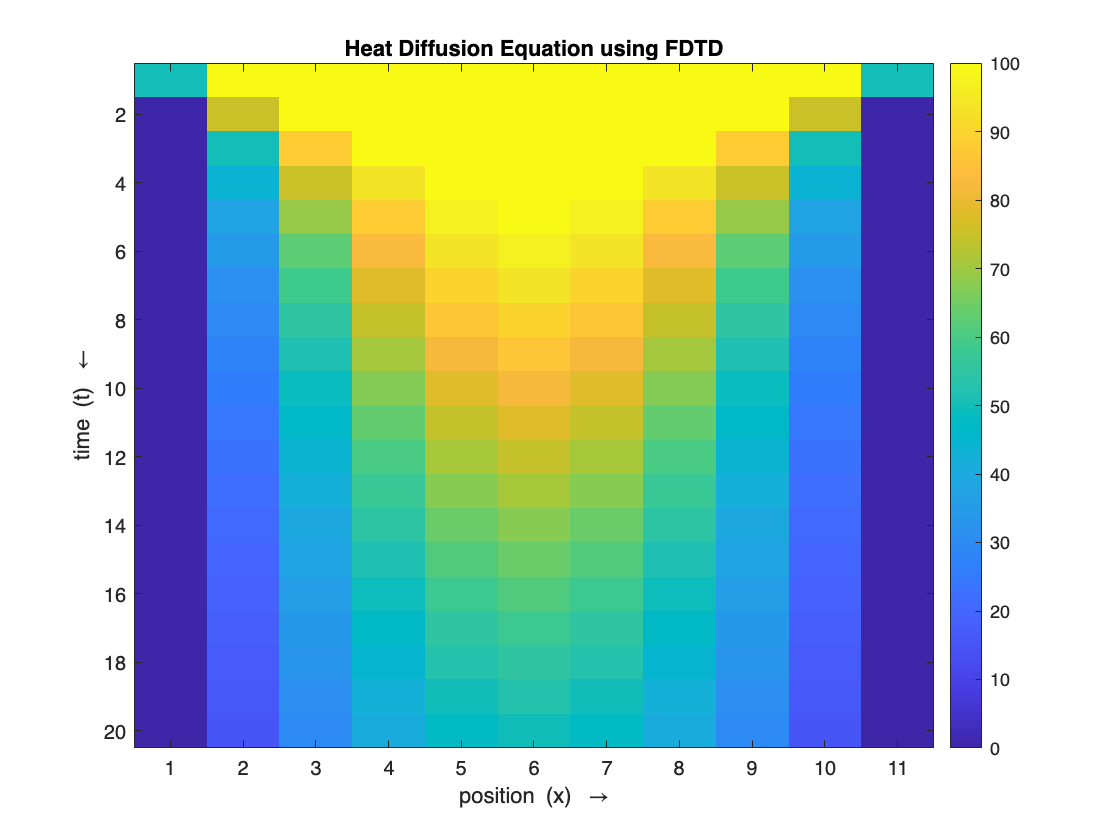

clear ALL;
clc;

del_x = 0.1;
r = 0.5;
del_t = r * del_x^2;

out_init = zeros(round(del_x / del_t), 7); % initializing grid
out_init(:,  1) = 0; % boundary conditions, eq. 3
out_init(1, 2:end) = 100; % initial condition, eq. 4

% finite differencing, eq. 2
out_init(1, 1) = 50;
for i = 2:size(out_init, 1)
    for j = 2:size(out_init, 2)-1
        out_init(i, j) = (out_init(i - 1, j + 1) + out_init(i - 1, j - 1)) * 0.5;
    end
    out_init(i, end) = out_init(i, end-2);
end

out_final = [out_init, fliplr(out_init(:, 1:4))];

figure;
imagesc(out_final);
title("Heat Diffusion Equation using FDTD");
xlabel("position (x) \rightarrow");
ylabel("time (t) \leftarrow");
colorbar;

### Key takeaways $-$

- `imagesc` plots a graphical representation of a matrix, representing color intensities for matrix values.

- `fliplr` flips a matrix left to right.

- We can stack columns to a matrix just by the notation [existing matrix, new column or group of columns].

- Code for Experiment no. 2 can be downloaded from  